## divide train set and test set

data = X;
label = y;

% ratio = 0.75;
% num_train = floor(length(label)*ratio); 
% choose = randperm(length(label)); 

train_data  = data(choose(1:num_train), vsel_ga);
train_label = label(choose(1:num_train));
test_data   = data(choose(num_train+1:end), vsel_ga);
test_label  = label(choose(num_train+1:end));

tic
[bestacc0, bestc0, bestg0] = svm_gridsearch(train_label,...
                        train_data,-4, 2, -4, 2, 10, 1, 1, 0.2);
toc

*
optimization finished, #iter = 69
nu = 1.000000
obj = -8.584318, rho = 0.005275
nSV = 138, nBSV = 138
*
optimization finished, #iter = 69
nu = 0.992806
obj = -8.561955, rho = 0.975692
nSV = 138, nBSV = 138
*
optimization finished, #iter = 64
nu = 0.962406
obj = -7.960135, rho = -0.978275
nSV = 128, nBSV = 128
*
optimization finished, #iter = 69
nu = 0.992806
obj = -8.603404, rho = 0.989675
nSV = 138, nBSV = 138
*
optimization finished, #iter = 64
nu = 0.962406
obj = -7.987985, rho = -0.995150
nSV = 128, nBSV = 128
*
optimization finished, #iter = 64
nu = 0.955224
obj = -7.998074, rho = -0.998855
nSV = 128, nBSV = 128
Total nSV = 272
*
optimization finished, #iter = 68
nu = 1.000000
obj = -8.457862, rho = 0.005064
nSV = 136, nBSV = 136
*
optimization finished, #iter = 68
nu = 0.992701
obj = -8.436811, rho = 0.975443
nSV = 136, nBSV = 136
*
optimization finished, #iter = 64
nu = 0.969697
obj = -7.958041, rho = -0.976253
nSV = 128, nBSV = 128
*
optimization finished, #iter = 68
nu = 0.9

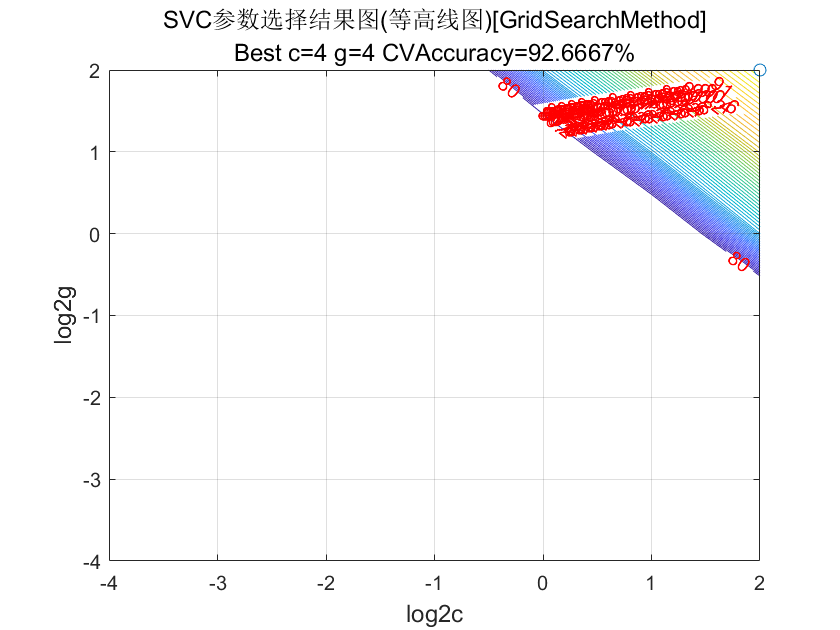

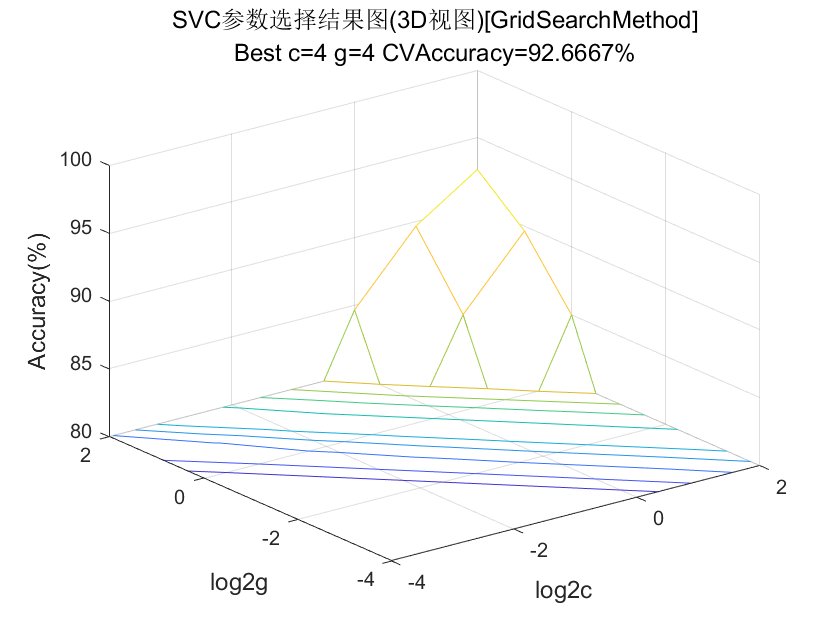

tic
[bestacc, bestc, bestg] = svm_gridsearch(train_label,...
                        train_data,0, 2, 0, 2, 10, 0.1, 0.1, 0.1);

toc

历时 3.255550 秒。


*
optimization finished, #iter = 39
nu = 0.392451
obj = -37.496971, rho = -0.057057
nSV = 56, nBSV = 51
*
optimization finished, #iter = 69
nu = 0.514713
obj = -44.060035, rho = 0.694374
nSV = 74, nBSV = 68
*
optimization finished, #iter = 66
nu = 0.783341
obj = -91.028810, rho = 0.072132
nSV = 115, nBSV = 111
*
optimization finished, #iter = 59
nu = 0.416379
obj = -33.334923, rho = 0.417773
nSV = 56, nBSV = 50
*
optimization finished, #iter = 28
nu = 0.260438
obj = -22.724046, rho = 0.162192
nSV = 36, nBSV = 32
*
optimization finished, #iter = 41
nu = 0.333333
obj = -26.976649, rho = -0.211763
nSV = 46, nBSV = 46
Total nSV = 204
*
optimization finished, #iter = 37
nu = 0.381757
obj = -35.756686, rho = -0.078390
nSV = 53, nBSV = 48
*
optimization finished, #iter = 50
nu = 0.529875
obj = -44.833999, rho = 0.719782
nSV = 74, nBSV = 69
*
optimization finished, #iter = 66
nu = 0.795263
obj = -90.208162, rho = 0.342694
nSV = 114, nBSV = 110
*
optimization finished, #iter = 49
nu = 0.405579


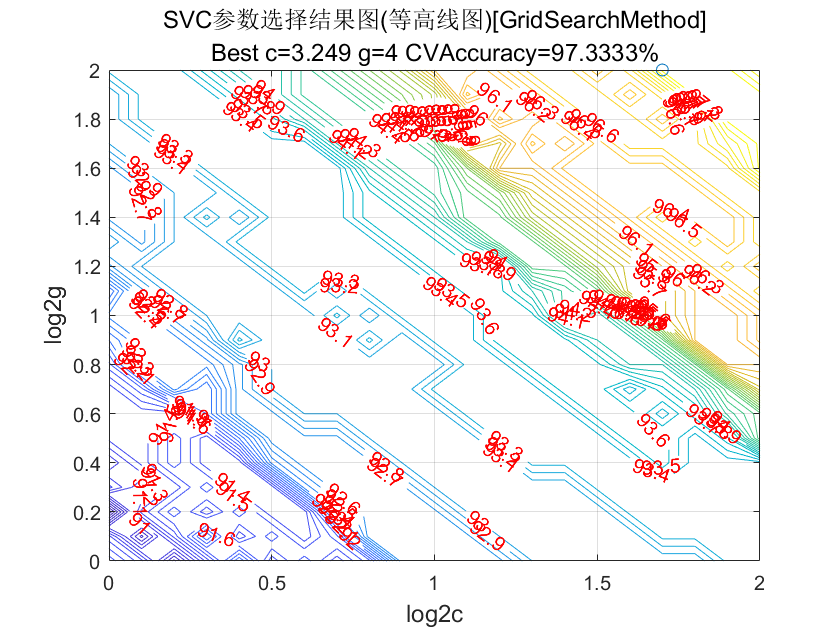

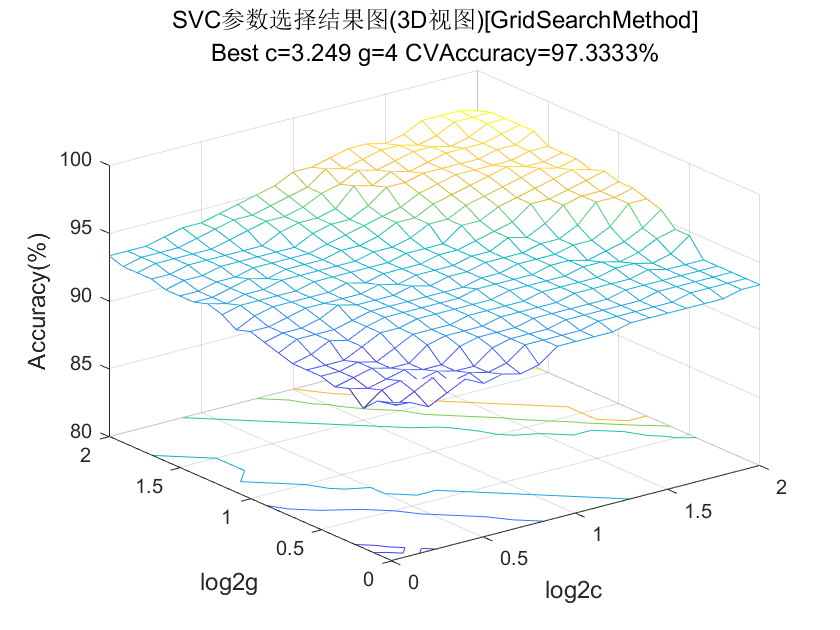

s = 0;
t = 0;
c = bestc;

g = bestg;

历时 23.235106 秒。


options = [' -s ',num2str(s),' -t ',num2str(t),' -c ',num2str(c),' -g ',num2str(g)]; 
model = libsvmtrain(train_label, train_data, options); 

[train_pred_label, train_acc, ~]...
           = libsvmpredict(train_label, train_data, model);
[test_pred_label, test_acc, ~]...
           = libsvmpredict(test_label, test_data, model);

*
optimization finished, #iter = 45
nu = 0.365000
obj = -299.193378, rho = 3.396428
nSV = 56, nBSV = 52
*
optimization finished, #iter = 39
nu = 0.295568
obj = -254.638726, rho = 5.846380
nSV = 48, nBSV = 44
*
optimization finished, #iter = 30
nu = 0.361303
obj = -309.411490, rho = 8.497454
nSV = 54, nBSV = 52
*
optimization finished, #iter = 42
nu = 0.360765
obj = -280.099188, rho = 3.812399
nSV = 56, nBSV = 53
*
optimization finished, #iter = 56
nu = 0.449900
obj = -335.115797, rho = 4.367168
nSV = 69, nBSV = 64
*
optimization finished, #iter = 70
nu = 0.905405
obj = -887.538424, rho = -7.548605
nSV = 134, nBSV = 134
Total nSV = 216


Accuracy = 88% (264/300) (classification)


Accuracy = 86% (86/100) (classification)
